## Introduction to Image Stitching

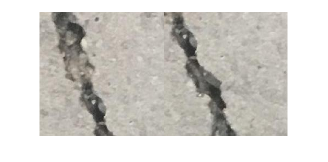

movingImg = imread("00475.jpg");
fixedImg = imread("00476.jpg");
montage({movingImg,fixedImg})

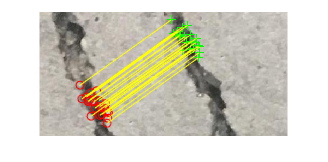


regOutput = registerConcreteImages(movingImg,fixedImg);
showMatchedFeatures(movingImg,fixedImg,regOutput.MovingMatchedFeatures,regOutput.FixedMatchedFeatures,"montage");

movingT = regOutput.Transformation;
fixedT = rigidtform2d();

[nrows, ncols, ~] = size(movingImg);
[xlimMoving, ylimMoving] = outputLimits(movingT,[1 ncols],[1 nrows])

xlimMoving = 1×2 の single 行ベクトル
  -59.0444  167.0071


ylimMoving = 1×2 の single 行ベクトル
 -119.0043  107.0472


[xlimFixed, ylimFixed] = outputLimits(fixedT,[1 ncols],[1 nrows])

xlimFixed =      1   227


ylimFixed =      1   227



xMin = min([xlimMoving, xlimFixed]);
xMax = max([xlimMoving, xlimFixed]);
yMin = min([ylimMoving, ylimFixed]);
yMax = max([ylimMoving, ylimFixed]);

w = round(xMax - xMin);
h = round(yMax - yMin);

panorama = zeros([h,w,3],"uint8");

blender = vision.AlphaBlender("Operation","Binary Mask","MaskSource","Input port")

blender =   vision.AlphaBlender のプロパティ:

         Operation: 'Binary mask'
        MaskSource: 'Input port'
    LocationSource: 'Property'
          Location: [1 1]


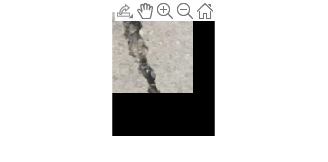


panoramaView = imref2d([h w],[xMin xMax],[yMin yMax]);

movingWarped = imwarp(movingImg,movingT,"OutputView",panoramaView);
fixedWarped  = imwarp(fixedImg,fixedT,"OutputView",panoramaView);
imshow(movingWarped)

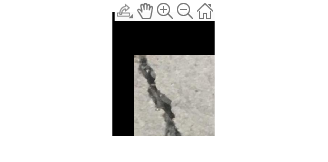

imshow(fixedWarped)

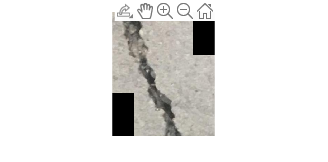


mask = ones(nrows, ncols, "logical");
fixedMask = imwarp(mask, fixedT, "OutputView", panoramaView);
movingMask = imwarp(mask, movingT, "OutputView", panoramaView);

panorama = blender(panorama,movingWarped,movingMask);
panorama = blender(panorama,fixedWarped,fixedMask);
imshow(panorama)

## Stitching Images Example

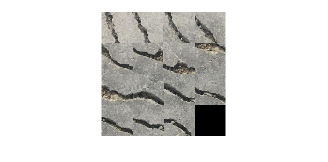

% dir = uigetdir('..\..\Data\Concrete Registration',"Select Concrete Registration folder");
dir = '..\..\Data\Concrete Registration';
imds = imageDatastore(dir);
montage(imds)

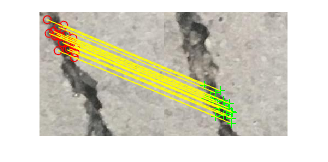

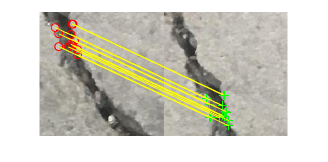

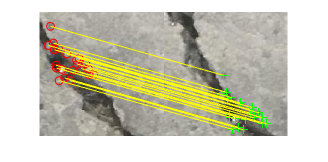

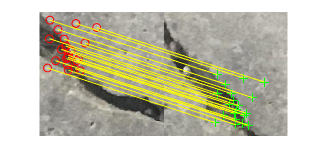

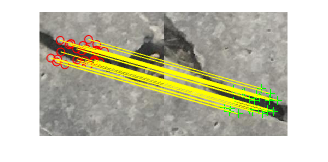

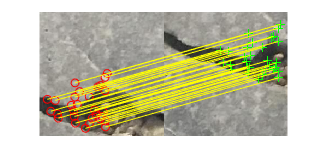

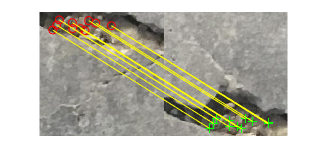

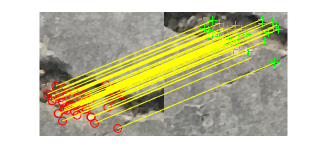


numImages = numel(imds.Files);
tforms(numImages) = rigid2d();
[sizeX,sizeY,~] = size(readimage(imds,1));

for i = 2:numImages
    img1 = readimage(imds,i-1);
    img2 = readimage(imds,i);
    regOutput = registerConcreteImages(img2,img1);
    
%     if i==3
%         [regOutput.MovingMatchedFeatures,regOutput.FixedMatchedFeatures] = ...
%             cpselect(img2,img1,"Wait",true);
%         regOutput.Transformation = estgeotform2d( ...
%             regOutput.MovingMatchedFeatures,regOutput.FixedMatchedFeatures,...
%             "rigid");
% %         regOutput.Transformation = regOutput.Transformation.A;
%     end


    figure
    showMatchedFeatures(img2,img1,regOutput.MovingMatchedFeatures,regOutput.FixedMatchedFeatures,"montage")

    tforms(i) = regOutput.Transformation;
%     tforms(i).T = tforms(i).T * tforms(i-1).T;
    tforms(i).T = tforms(i-1).T * tforms(i).T;
end

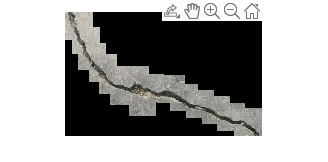


[lastXlim,lastYlim] = outputLimits(tforms(end),[1 sizeX],[1 sizeY]);
trans = [mean(lastXlim) mean(lastYlim)];
rot = [1 0;
       0 1];
lastTform = rigid2d(rot,trans);
for i=1:numel(tforms)
    tforms(i).T = lastTform.invert.T * tforms(i).T;
end

for i=1:numel(tforms)
    [xlim(i,:),ylim(i,:)] = outputLimits(tforms(i),[1 sizeX],[1 sizeY]);
end

xMin = min(xlim(:));
xMax = max(xlim(:));
yMin = min(ylim(:));
yMax = max(ylim(:));

imgWidth = round(xMax - xMin);
imgHeight = round(yMax - yMin);

panorama = zeros([imgHeight imgWidth, 3], "uint8");

blender = vision.AlphaBlender("Operation","Binary Mask","MaskSource","Input port");
panoramaView = imref2d([imgHeight imgWidth],[xMin xMax],[yMin yMax]);

for i=1:numImages
    img = readimage(imds,i);
    warpedImage = imwarp(img,tforms(i),"OutputView",panoramaView);
    mask = imwarp(true(size(img,[1 2])),tforms(i),"OutputView",panoramaView);
    panorama = step(blender,panorama,warpedImage,mask);
end

imshow(panorama)

## Concept Check: Image Stitching

Q1. `outputLimits`

Q2. It is used with the `imwarp` function to place the warped image at coordinates determined by the spatial referencing object.

Q3. True

Q4. Add a for loop that multiplies all transforms by the inverse of the center image's transform.

## Mars Rover: Your Final Project

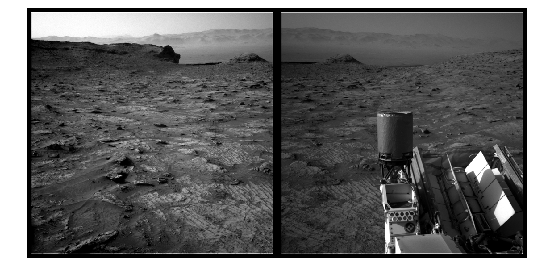

fixedImg = imread("sol_03333_opgs_edr_ncam_NLB_693387385EDR_F0921230NCAM00259M_.JPG");
movingImg = imread("sol_03333_opgs_edr_ncam_NLB_693387301EDR_F0921230NCAM00259M_.JPG");
montage({movingImg,fixedImg},"BorderSize",[10 10])

registrationEstimator

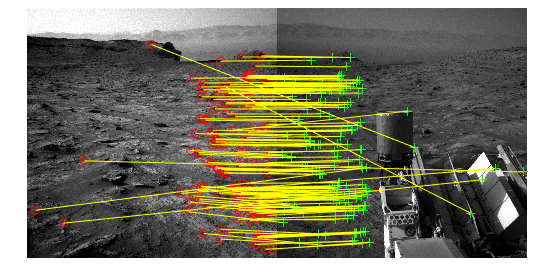

regOutput = registerMarsImages(movingImg,fixedImg);
showMatchedFeatures(movingImg,fixedImg,regOutput.MovingMatchedFeatures,regOutput.FixedMatchedFeatures,"montage")

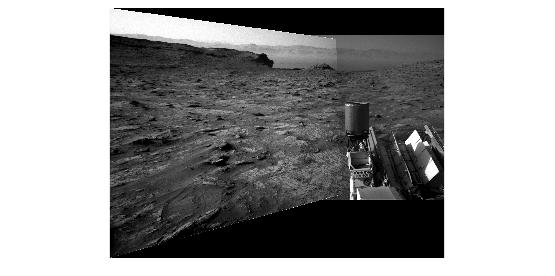

movingT = regOutput.Transformation;
fixedT = rigidtform2d();
[sizeX, sizeY] = size(fixedImg); % 画像サイズは同じ
[xlimMoving,ylimMoving] = outputLimits(movingT,[1 sizeY],[1 sizeX]);
[xlimFixed,ylimFixed] = outputLimits(fixedT,[1 sizeY],[1 sizeX]);

xMin = min([xlimMoving,xlimFixed]);
xMax = max([xlimMoving,xlimFixed]);
yMin = min([ylimMoving,ylimFixed]);
yMax = max([ylimMoving,ylimFixed]);

imgWidth = round(xMax - xMin);
imgHeight = round(yMax - yMin);

panorama = zeros([imgHeight imgWidth],"uint8");

blender = vision.AlphaBlender("Operation","Binary Mask","MaskSource","Input port");
panoramaView = imref2d([imgHeight imgWidth],[xMin xMax],[yMin yMax]);

mask = true([sizeX sizeY]);
fixedWarped = imwarp(fixedImg,fixedT,"OutputView",panoramaView);
fixedMask = imwarp(mask,fixedT,"OutputView",panoramaView);
movingWarped = imwarp(movingImg,movingT,"OutputView",panoramaView);
movingMask = imwarp(mask,movingT,"OutputView",panoramaView);

panorama = step(blender,panorama,fixedWarped,fixedMask);
panorama = step(blender,panorama,movingWarped,movingMask);
% panorama = blender(panorama,movingWarped,movingMask);
% panorama = blender(panorama,fixedWarped,fixedMask);

imshow(panorama)

testMarsImage(panorama)

Success!
Enter the number: 1984 into the final quiz question.


## [Quiz] Project: Check the Panorama Image

Q1. [-1050, 1024]

Q2. [-164, 1385]

Q3. [1550, 2073]

Q4. 1984

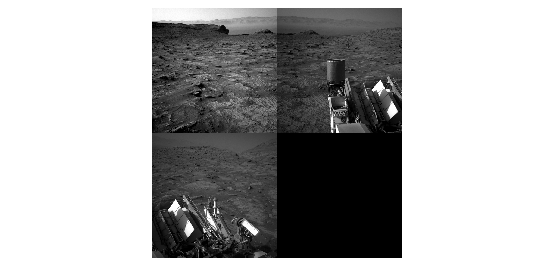

% dir = uigetdir();
dir = '..\..\Data\Mars Curiosity Rover';
imds = imageDatastore(dir);
montage(imds)

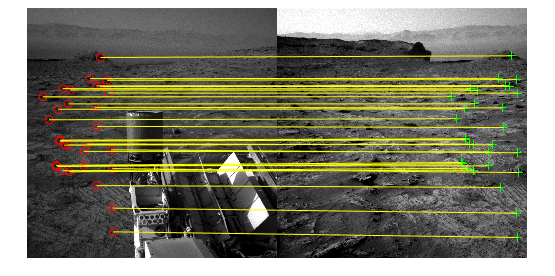


numImages = numel(imds.Files);
tforms(numImages) = projective2d();
[sizeX, sizeY] = size(readimage(imds,1));

for i=ceil(numImages/2)-1:-1:1
    fixed = readimage(imds,i+1);
    moving = readimage(imds,i);
    
    regOutput = registerMarsImages2(moving,fixed);

    figure;
    showMatchedFeatures(fixed,moving,regOutput.FixedMatchedFeatures,regOutput.MovingMatchedFeatures,"montage")

    tforms(i) = regOutput.Transformation;
    tforms(i).T = tforms(i+1).T * tforms(i).T;
end

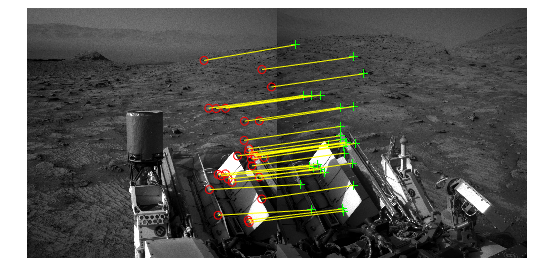

for i=ceil(numImages/2)+1:numImages
    fixed = readimage(imds,i-1);
    moving = readimage(imds,i);
    
    regOutput = registerMarsImages2(moving,fixed);

    figure;
    showMatchedFeatures(fixed,moving,regOutput.FixedMatchedFeatures,regOutput.MovingMatchedFeatures,"montage")

    tforms(i) = regOutput.Transformation;
    tforms(i).T = tforms(i-1).T * tforms(i).T;
end

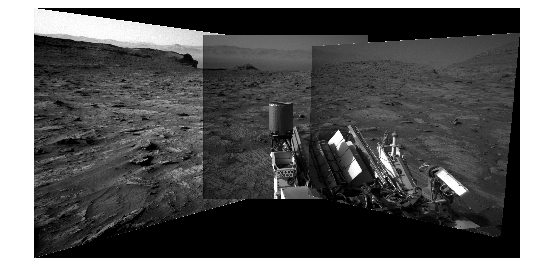


for i=1:numImages
    [xlim(i,:),ylim(i,:)] = outputLimits(tforms(i),[1 sizeX],[1 sizeY]);
end

xMin = min(xlim(:));
xMax = max(xlim(:));
yMin = min(ylim(:));
yMax = max(ylim(:));

imgWidth = round(xMax - xMin);
imgHeight = round(yMax - yMin);

% centerTform = rigidtform2d([1 0 -imgWidth/2; ...
%                             0 1 -imgHeight/2; ...
%                             0 0 1]);
% for i=1:numImages
%     tforms(i).T = centerTform.T * tforms(i).T;
% end
% 
% for i=1:numImages
%     [xlim(i,:),ylim(i,:)] = outputLimits(tforms(i),[1 sizeX],[1 sizeY]);
% end
% 
% xMin = min(xlim(:));
% xMax = max(xlim(:));
% yMin = min(ylim(:));
% yMax = max(ylim(:));
% 
% imgWidth = round(xMax - xMin);
% imgHeight = round(yMax - yMin);

panorama = zeros([imgHeight imgWidth],"uint8");

blender = vision.AlphaBlender("Operation","Binary Mask","MaskSource","Input port");
panoramaView = imref2d([imgHeight imgWidth],[xMin xMax],[yMin yMax]);

for i=1:numImages
    img = readimage(imds,i);
    warpedImage = imwarp(img,tforms(i),"OutputView",panoramaView);
    mask = imwarp(true(size(img,[1 2])),tforms(i),"OutputView",panoramaView);
    panorama = step(blender,panorama,warpedImage,mask);
end
imshow(panorama)

% 調整用
img1 = readimage(imds,1);
img2 = readimage(imds,2);
img3 = readimage(imds,3);

clear